%%STARE
% images ='D:\workspace\DIP\oRGB\dataset\stare-photos';  
% files=dir(fullfile(images,'\*.ppm*'));

%% DIARET DB0
images ='D:\workspace\DIP\oRGB\dataset\diaretdb0_v_1_1\resources\images\diaretdb0_fundus_images';  
files=dir(fullfile(images,'\*.png*'));

%%

n1=numel(files);                                       
 

idx = 50

idx = 50

im = files(idx).name;
disp(strcat("working on: ",im))

working on: image050.png


inImg = imread(fullfile(images,im)); 


% ROI
[X, inx] = ROI(inImg);

[R,C,~] = size(inImg);
inx_bool = zeros(R*C,1);
inx_bool(inx) = 1;

scale = 6;
left_tile = 8; %increase, increase contrast
% right_tile = 14;
tiles = [left_tile left_tile];
clipLimit = 0.02;
distribution = "rayleigh";

L = 51.4732;
A = 34.5079;
B = 51.055;

BR_L = 32.3438;
BR_A = 65.8206;
BR_B = 30.0466;

[Z,LABp] = claheLab(X, inx,scale,tiles, clipLimit,distribution,[L A B],[BR_L BR_A BR_B]);

tmp = uint8(Z*255);

tmp3 = reshape(tmp,[],3);
meanRGB = mean(tmp3(inx,:))

meanRGB =   191.9536   95.1149   31.8392


m3 = m3colorfulness(tmp3)

m3 = 93.0944

gcf = getGlobalContrastFactor(tmp(:,:,2))

gcf = 3.0007

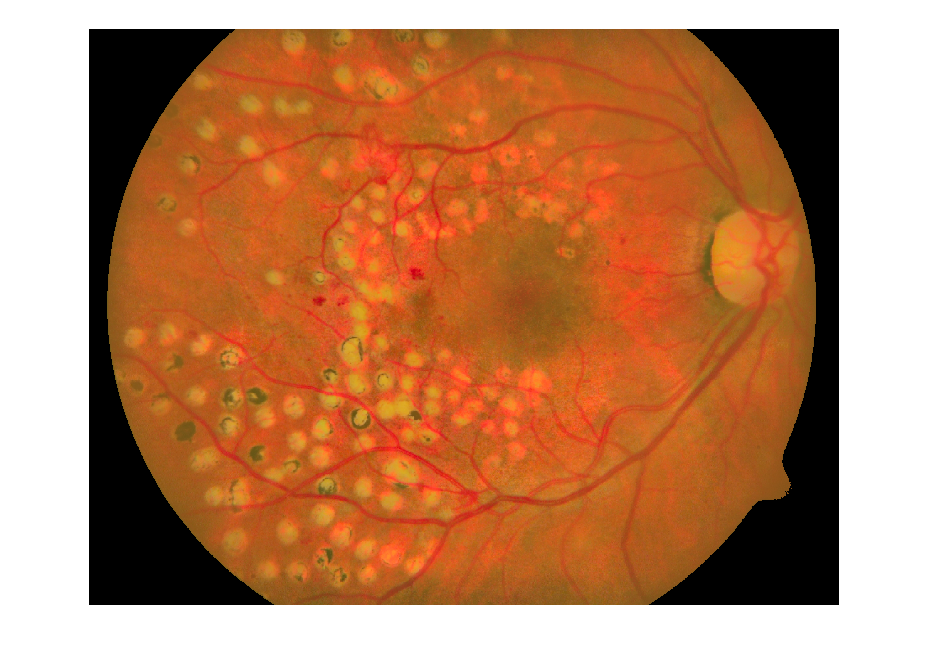



tmp4 = tmp3;
tmp4(~inx_bool,:) = 0;
rgb = reshape(tmp4,size(inImg));

figure, imshow(rgb)

    
%% save to file
%     im = split(im,".");
%     im = strcat(dest_path,"\",im(1),".png");
%     imwrite(Z,im);
